# Data Visualisation

Visualising data properly is a key part of science, particularly research. In this workshop we will show you how to visualise data in MATLAB in different ways. 

### Your first plot!

When plotting you should always start by initialising a plot using the keyword `figure`

figure; % This allows MATLAB to know you are working on a new plot, in case previous plots were created before.

You can always return to old plots by putting the number of the plot next to the keyword `figure` (e.g. "`figure(1)")`

Plotting simple curves in matlab is done using the `plot` function. This follows the structure: 

`plot(x,y,parameters)`

Where parameters can indicate things such as the colour of the line, the type of the line (e.g. dotted line), or the width of the line.

For example, we can add to the figure an identity line:

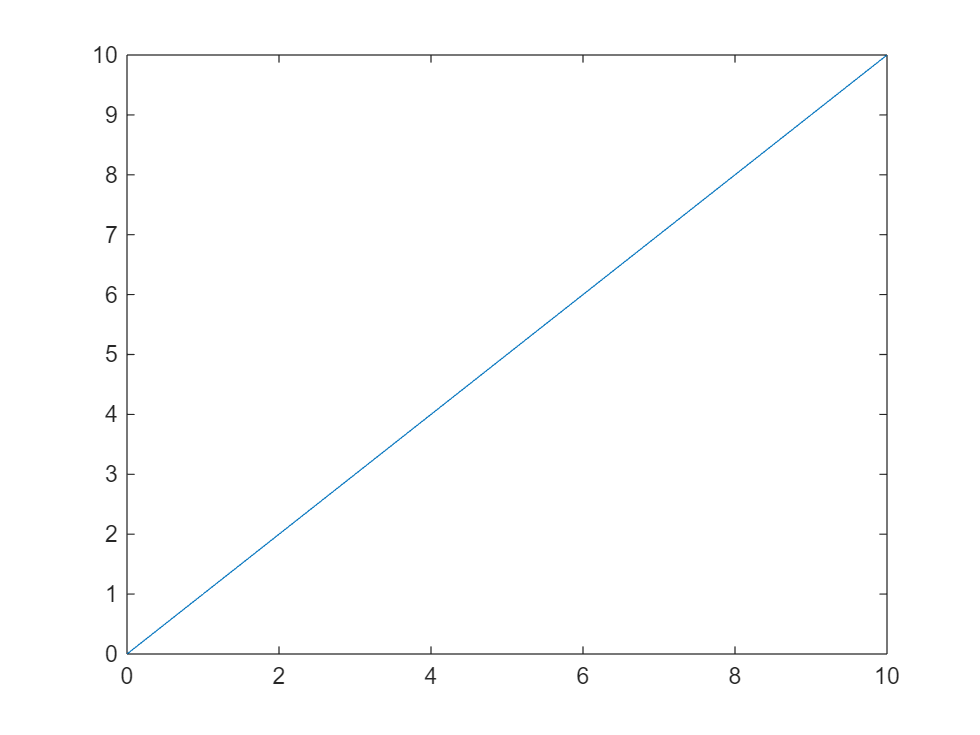

plot(0:10,0:10)

This line can be adjusted using line parameter keywords, containing the colour (for example `'r', 'b', 'g'` are characters for red blue and green) and containing the line type (for example `'-', '*', '--' `are keystrings for continous line, star markers, and dotted lines).

Exercise 1.

Using the absolute value function `abs, `create an x-axis ranging from -5 to 5 in steps of 0.5, and plot the absolute value of the function in a red dotted line

x = [] % x-axis


x =

     []



y = [] % Resulting function


y =

     []



plot(x,y,'') % Put the params here

### Plot parameters

We have seen a very simple plot, and have seen how to change the colour and linestyle of our curves, now let's look at more ways to change our plots.

**Multiple curves**

You can plot multiple curves on a plot by using the `hold` keyword. If you write `"hold on",` the current figure will keep previous curves/plot parameters when adding new curves to the plot, to revert back to the default behaviour, you can write "`hold off`".

**Titles and axis labels**

To make the life of your reader more easy, it is important to add clear labels to your plots and your axes. To add a title to your plot you can use the `title() `function, for example `title("A beautiful plot") `would work. 

To label your axes you can use the `xlabel()` and `ylabel()` functions in the same way.

**Limits and axis ticks**

MATLAB puts limits to a plot by default, but often these are not the desired ones. To change the limits, you can use the `xlim()` and `ylim()` functions. For example `xlim([0,1])` would set the x-axis limits to be 0 and 1.

The ticks of your axes are also set by default, but can be changed using the `xticks` and `yticks` functions. For example `xticks(0:0.5:1)` would change your ticks to be spaced from 0 to 1 at steps of 0.5. Additionally, if you want to give your ticks different labels, you can use the `xticklabels `and `yticklabels` functions, For example `xtickslabels(["A","B","C"])` would change the previous ticks from 0, 0.5, 1 -> "A", "B", "C".

**Legends**

Once a plot has been made, you can plot a legend using the `legend()` function, where the first argument is the list of labels. For example, we could write `legend(["Curve 1"; "Curve 2"]). `This can be turned off by writing `legend('off')`. 

Another way to set legends is by using the `'DisplayName' `keyword in the `plot()` function. For example: 

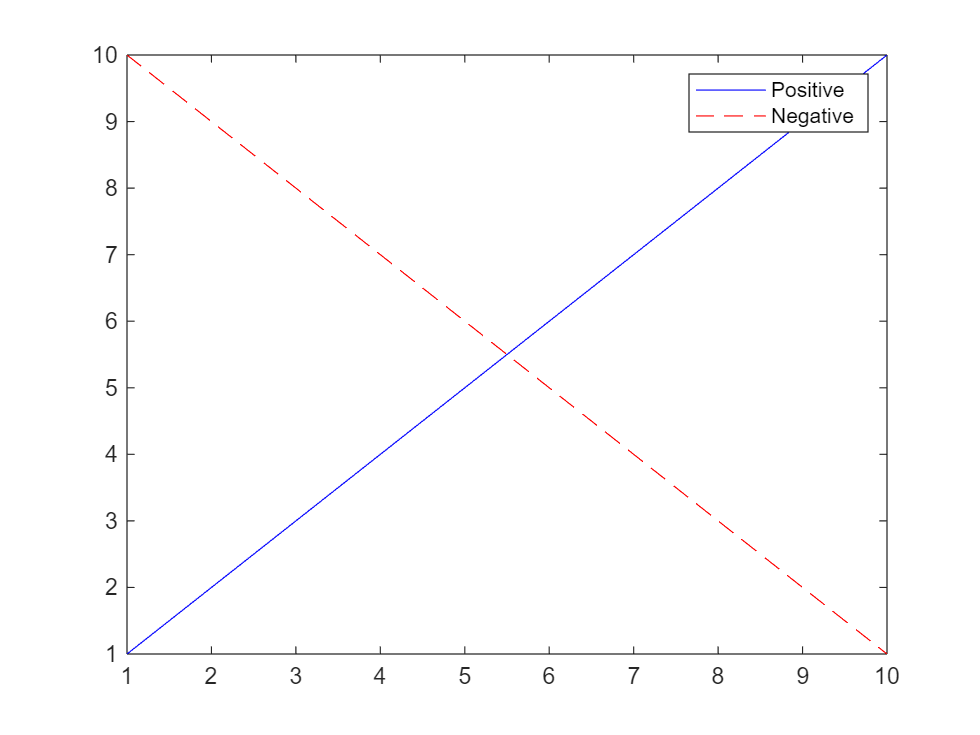

plot(1:10,1:10,'b-','DisplayName','Positive') % Note the structure of plot(x,y,'linespec','KEYWORD','ARGUMENT')
hold on
plot(1:10,10:-1:1,'r--','DisplayName','Negative')
legend()

Here the `legend()` function doesn't need any arguments.

*Exercise 2*

Using all of the information you just learn, performing the following tasks:

- Generate an x-axis of linearly spaced points from 0 to 2*pi (use the `linspace(start,stop,steps)` function)

- Compute the sin, cos, sin^2 and cos^2 of this array

- Plot the cos and cos^2 in blue and the sin and sin^2 in red.

- Plot the sin and cos with continous lines and plot the squared versions with dotted lines

- Give your plot a relevant title

- Plot a horizontal green line at `y=0`

- Plot the legend, giving a name to all the periodic curves but not the horizontal line

- Make your x-axis display the ticks at [0, pi/2, pi, 3pi/2, 2pi]

- Label your x-axis to show pi instead of the decimal numbers (You can use a backslash `"\"` in front of pi, such as `"\pi/2"` to make it print the pi simbol)

- Make your y-axis display the ticks from -1 to 1 in steps of 0.25

- Change your x-axis and y-axis limits to perfectly fit the curves

- Give your x-axis and y-axis relevant names

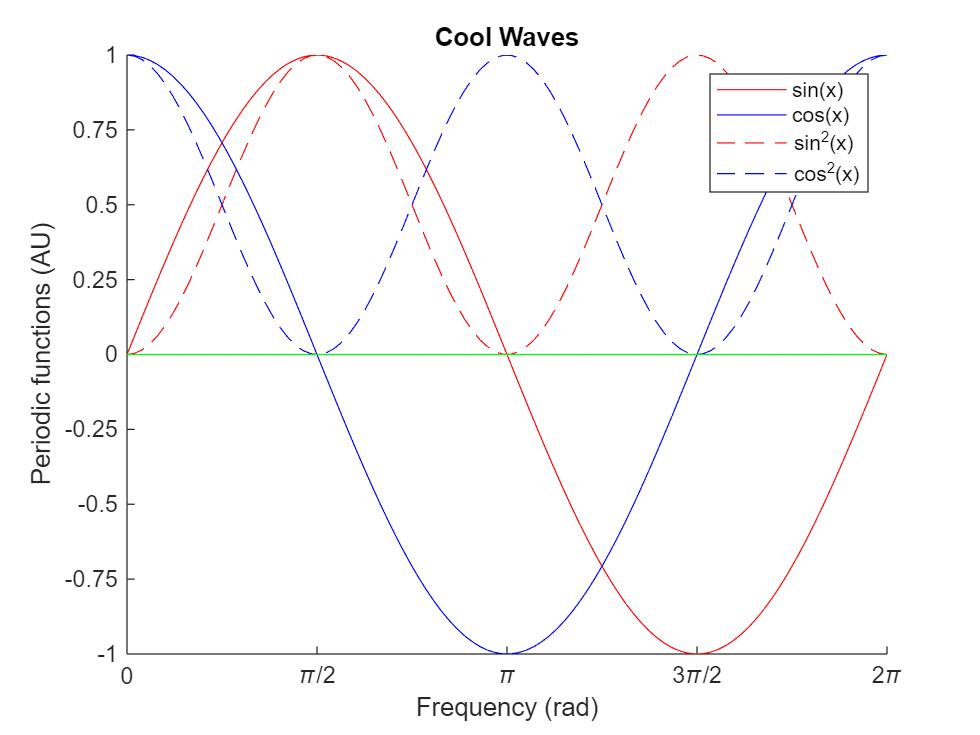

x = linspace(0,2*pi,100);
sinx = sin(x);
cosx = cos(x);
sin2x = sin(x).^2;
cos2x = cos(x).^2;
figure;
hold on;
plot(x,sinx, 'r-')
plot(x,cosx, 'b-')
plot(x,sin2x, 'r--')
plot(x,cos2x, 'b--')
plot(x,zeros(length(x)), 'g-')
xlim([0,2*pi])
ylim([-1,1])
xticks(0:pi/2:2*pi)
yticks(-1:0.25:1)
xticklabels(["0","\pi/2","\pi","3\pi/2","2\pi"])
xlabel("Frequency (rad)")
ylabel("Periodic functions (AU)")
title("Cool Waves")
legend(["sin(x)","cos(x)","sin^2(x)","cos^2(x)"])

### Subplots

Subplots are extremely useful, since they allow to visualise different plots in one go. Subplots in matlab are used with the `subplot` sintax in the following way:

`subplot(rows,columns,current)`. Where `rows` and `columns` are the overall number of rows and columns in the whole plot and current is the index of the current subplot. Look at the example below:

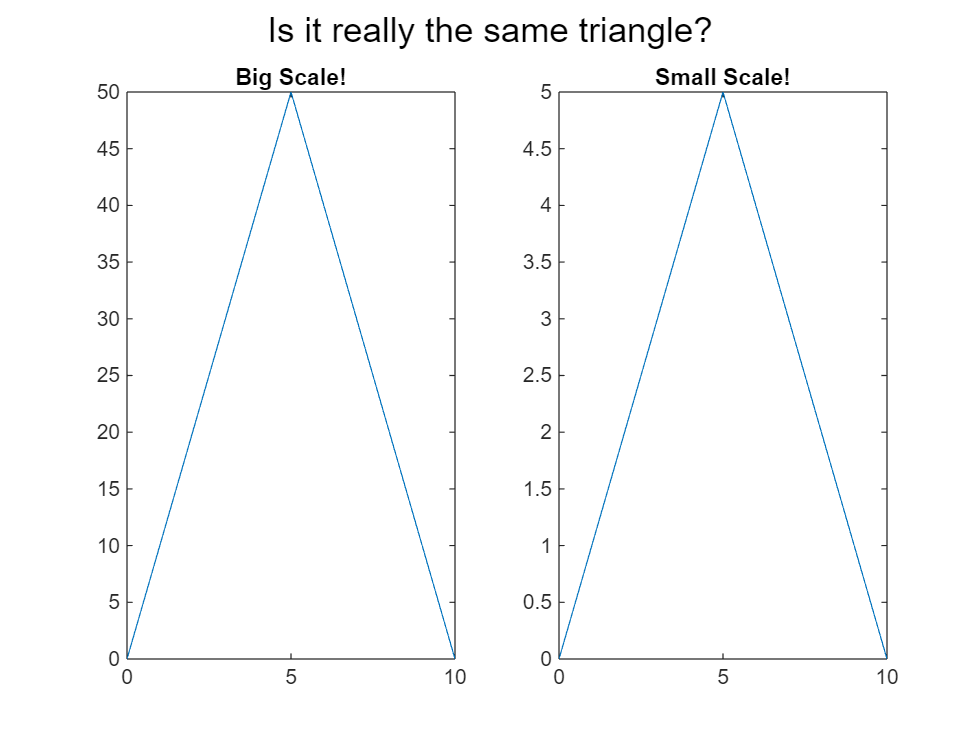

figure;
x = 0:10;
subplot(1,2,1);
plot(x,[0:10:50, 40:-10:0])
title("Big Scale!") % Subplot title

subplot(1,2,2)
plot(x,[0:1:5,4:-1:0])
title("Small Scale!") % Subplot title

sgtitle("Is it really the same triangle?") % Overall title

*Exercise 3*

Take your code from exercise 2, and instead plot each of the periodic curves in a different subplot, from a 2x2 grid. sin(x) should be at the top-left corner, cos(x) at the top-right corner, sin^2(x) at the bottom-left corner, and cos^2(x) at the bottom-left corner. In each subplot, plot a horizontal green line at the middle of the plot (this middle will change depending on the function you are using). Give each subplot a title, and give the overall plot a general title.

You shouldn't spent time on the axes, lines or legends. As long as you get the correct plots in the correct locations with the correct titles you will have completed the exercise.

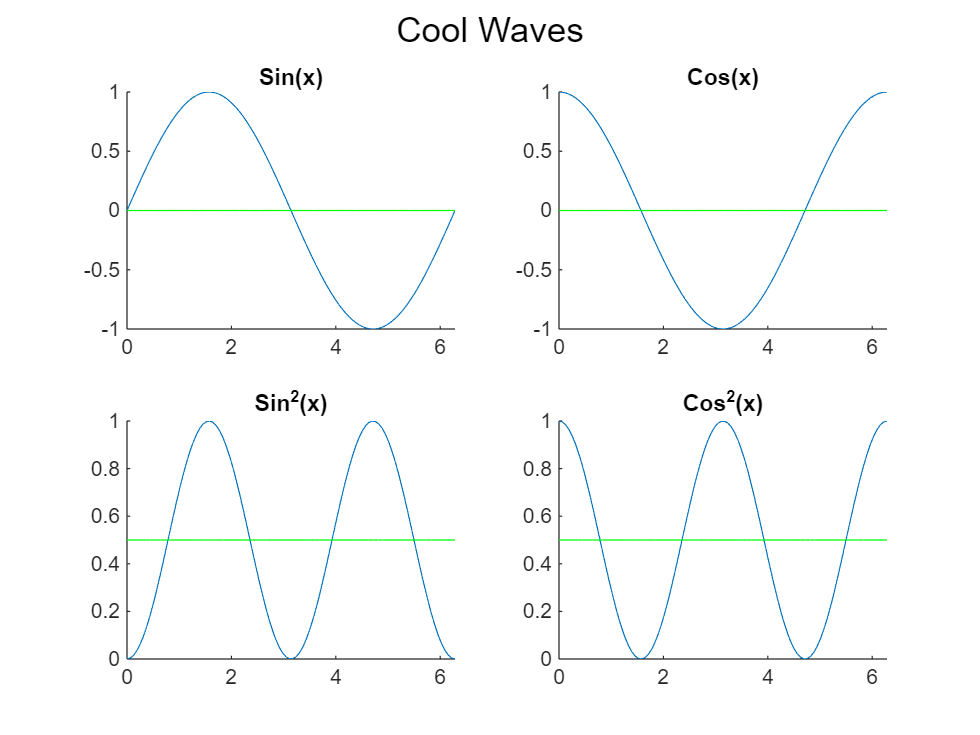

x = linspace(0,2*pi,100);
sinx = sin(x);
cosx = cos(x);
sin2x = sin(x).^2;
cos2x = cos(x).^2;
figure;
subplot(2,2,1)
hold on
plot(x,sinx)
plot(x,zeros(length(x)), 'g-')
title("Sin(x)")
subplot(2,2,2)
hold on
plot(x,cosx)
plot(x,zeros(length(x)), 'g-')
title("Cos(x)")
subplot(2,2,3)
hold on
plot(x,sin2x)
plot(x,0.5*ones(length(x)),'g-')
title("Sin^2(x)")
subplot(2,2,4)
hold on
plot(x,cos2x)
plot(x,0.5*ones(length(x)),'g-')
title("Cos^2(x)")
sgtitle("Cool Waves")

### Boxplots and Violin plots

Boxplots are a great way to visualize the distribution of data and identify key statistical information, such as the median, quartiles, and potential outliers in a population.

Let's create boxplots for a few different datasets.

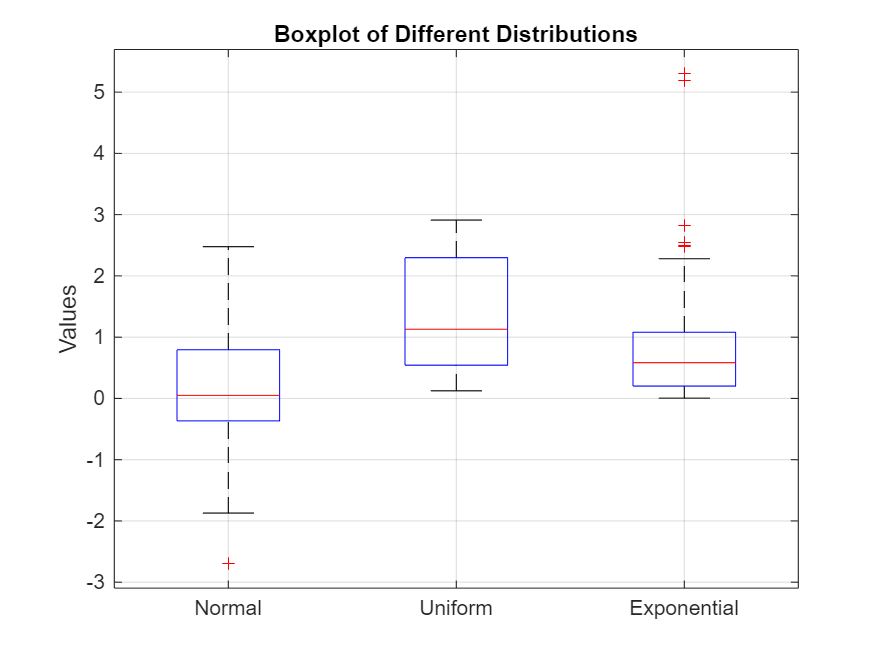

% Generate random data from different distributions
data1 = randn(50, 1); % Normal distribution
data2 = rand(50, 1) * 3; % Scaled Uniform distribution
data3 = exprnd(1, 50, 1); % Exponential distribution

% Combine the data into one matrix for comparison
data_matrix = [data1, data2, data3];

% Create a boxplot
f1 = figure;
boxplot(data_matrix, 'Labels', {'Normal', 'Uniform', 'Exponential'});
title('Boxplot of Different Distributions');
ylabel('Values');
grid on;

However, boxplots are limited in the sense that we do not see the population density in the boxes. 

A way to visualise our data distribution that can be added to a boxplot, is to plot the specific points of our population using `scatter`:

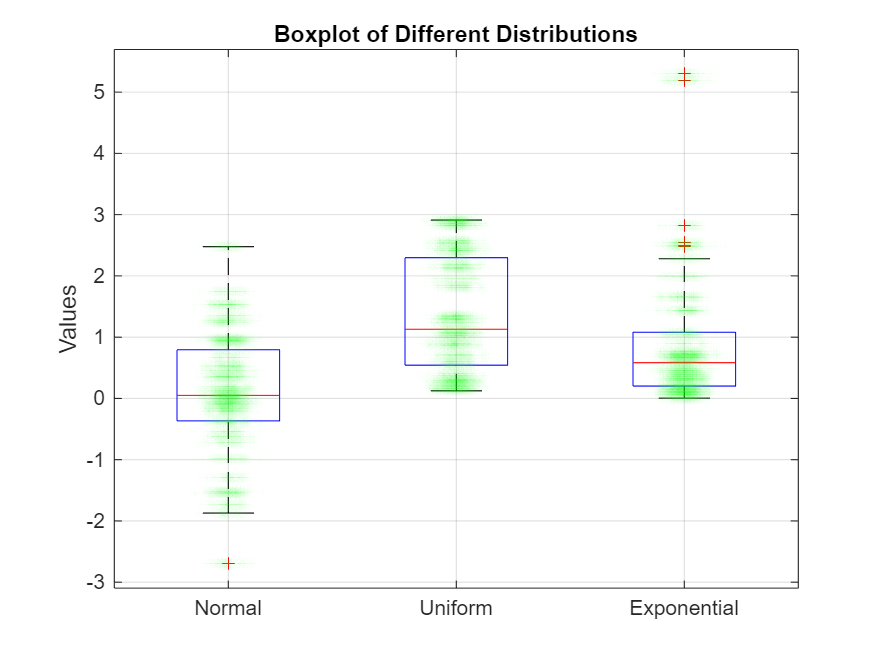

hold on
% If you are interested in understanding the line below, read the scatter
% function documentation

for i=1:3
    scatter(i+0.05*randn(length(data1)),data_matrix(:,i),'MarkerEdgeColor','g', 'MarkerEdgeAlpha',0.01,'MarkerFaceColor','none','Marker','*')
end

A better way to visualise this sort of data, is usually violin plots:

This next line of code makes sure to add violinplot to your functions, since only the most recent matlab version has it implemented:

try
    figure
    violinplot([])
    close
catch
    addpath Functions
end


Now let's do a violin plot:

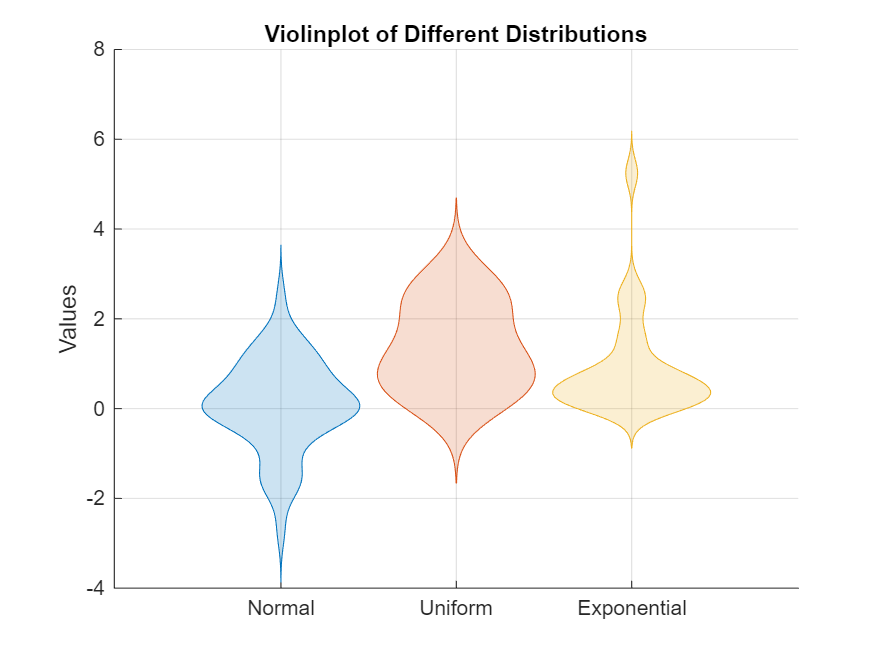


% Create a boxplot
figure;
violinplot(data_matrix);
title('Violinplot of Different Distributions');
ylabel('Values');
grid on;
xticklabels(["Normal","Uniform","Exponential"]) % This is added separately since violinplot reorders the labels otherwise

Since MATLAB doesn't have a built-in violin plot that shows a boxplot with it, you can use the combined plot function we created in Functions called my_violinplot:

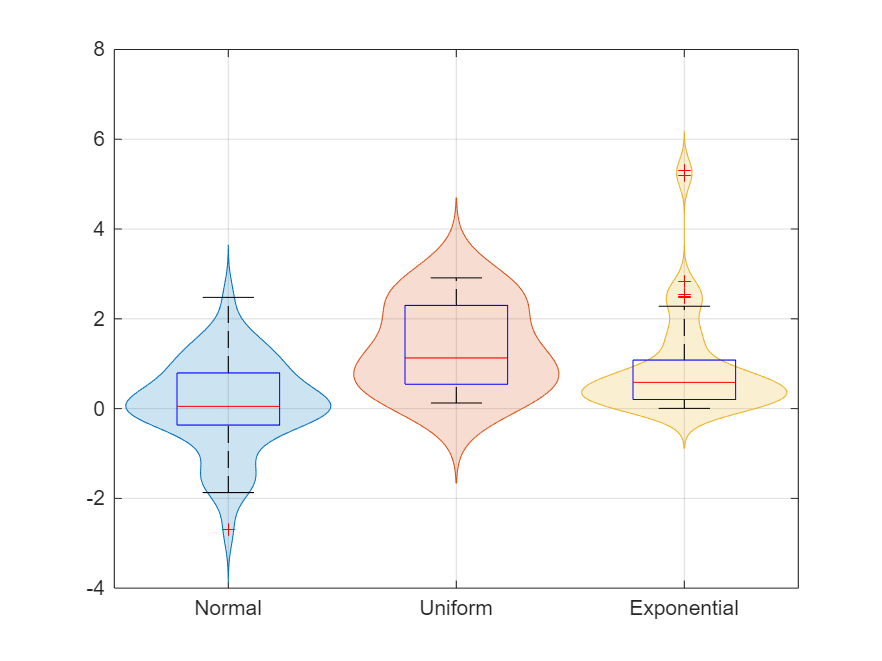

addpath Functions
my_violinplot(data_matrix,labels,true)